# **BSP 2021-2022/1 - Assignment 03**

  **Total of 10 marks**

**Name/Neptun Code: DMWBL1/ Hakan**   

**Marks attained for this homework will count towards your final grade**

**To attain (full) marks for a question, any answer that includes images or a piece of knowledge, which should be referenced/cited, needs to highlight the source (book, article or web address). You are encouraged to help each other, but identical solutions will not be graded.**

## **Modeling of neural activity**

You will model neural spiking with the Fitzhug-Nagumo model. This is a special case of the Van der Pol oscillator, and describes a relaxation oscillation, which is typical for neural activity.

The system of differential equations:


$$\dot{V} = V - \frac{V^3}{3} - W + I \\
\dot{W} = 0.08(V+a - bW)  $$


where $V
$is the membrane potential, $W
$is a recovery variable and $I
$is the magnitude of the stimulus current.

### Question 1

Solve the differential equation using ode45. Find parameters *a,b,I,V0,W0* resulting in a spike train (you can find some examples on [Wikipedia](https://en.wikipedia.org/wiki/FitzHugh–Nagumo_model), under the figures). Plot the timeline and the phase plot obtained. 

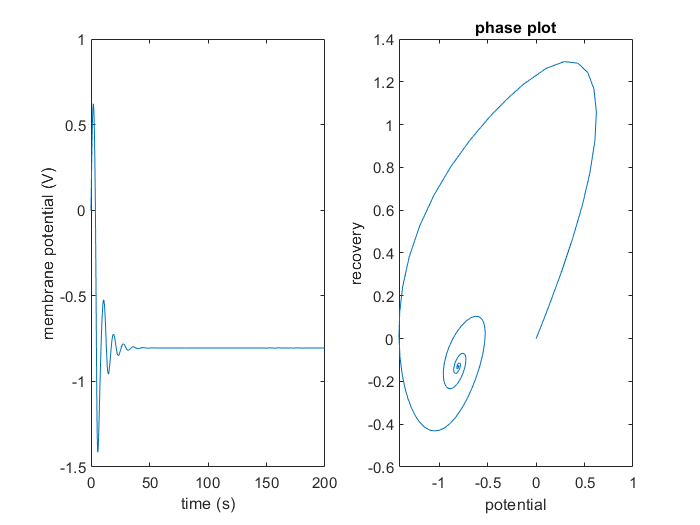

clear all
%parameters

V0 = 0;
W0 = 0;
a = 0.7;
b = 0.8;
I = 0.5;

timelimit = [0 200];

FitzhugNagumo(V0,W0,a,b,I,timelimit);

Complete the function FitzhugNagumo() at the end of this scrip**t** (function definitions must appear at the end of the file).

(2 marks)

### Question 2

How does the amount of injected current influence the output? Run FitzhugNagumo() with the modified parameters (at least 3 examples), and show the difference.

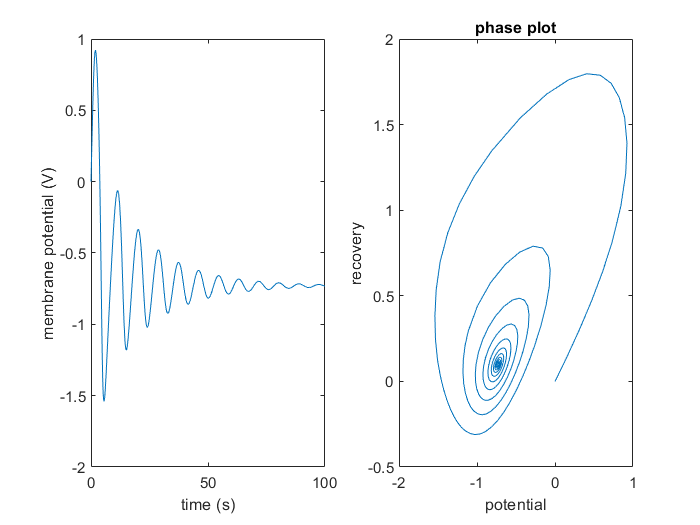

FitzhugNagumo(0,0,0.8,0.7,0.5,[0 100])
FitzhugNagumo(0,0,0.8,0.7,0.1,[0 100])
FitzhugNagumo(0,0,0.8,0.7,0.7,[0 100])

   In this example we changed specificaly Iext because as wiki says, if Iext exceeds a certain threshold value system will exhibit a characterstic excursion in phase  space before the variables VW(1) and VW(2) relax back to rest values.  This behaviour is typical for spike generations (a short, nonlinear elevation of membrane voltage {\displaystyle v}, diminished over time by a slower, linear recovery variable {\displaystyle w}) in a neuron after stimulation by an external input current.                                                                                                                                                            

(1 mark)

## Modeling of the ECG signal

This task is following the results of this article: [[link](https://ieeexplore.ieee.org/document/1186732)]. You can get access via institutional sign-in (start typing pazmany..), with your Pázmány shibboleth  user+password.

In his model the periodicity of the generated signal is granted by circular motion in the 3D-space. Each revolution around this limit circle corresponds to a single heart cycle. At the P-Q-R-S-T peaks the circular motion isnterrupted by exponential functions, which converge back to the limit cycle.

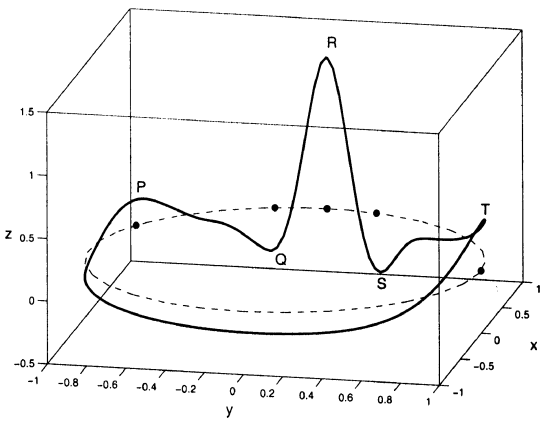

Fig. 1 Typical trajectory generated by the dynamical model in the 3-D space given by (x, y, z). The dashed line reflects the limit cycle of unit radius while the small circles show the positions of the P, Q, R, S, and T events. (Copy from [[link](https://ieeexplore.ieee.org/document/1186732)])

...

#### The ODE:

${\dot{x}=\,\alpha x-\omega y\\
\dot{y}=\,\alpha y+\omega x\\ 
\dot{z}=-\sum_{i\in\{P,Q,R,S,T\}}a_{i}\Delta\theta_{i}\exp\left(-{{\Delta\theta_{i}^{2}}\over{2b_{i}^{2}}}\right)-(z-z_{0})$          (1)

where $\alpha=1-\sqrt{x^{2}+y^{2}}$, $\Delta\theta_{i}=(\theta-\theta_{i})\ 

$*(use rem() in matlab for keeping the sign)*, $\theta=\hbox{atan}2(y,x)$, and $\omega$ s the angular velocity of the trajectory as it moves around the limit cycle. Baseline wander was introduced by coupling the baseline value z0 in [(1)](https://ieeexplore.ieee.org/document/#deqn1) to the respiratory frequency f2 using 


$$z_{0}(t)=A\sin(2\pi f_{2}t)$$
 

"

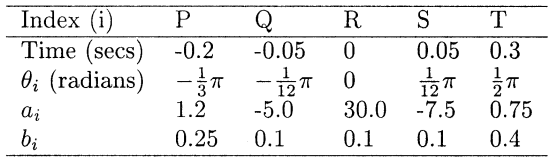

Table I. (Copy from [[link](https://ieeexplore.ieee.org/document/1186732)])

### Question 3

Following the above parts of the article's Section IV write the ODE of x,y,z, and generate a plot like Fig. 1.

Parameters from Table I.:

clear all

%parameters, i = {P,Q,R,S,T}
theta_i = [-1/3*pi,-1/12*pi,0,1/12*pi,1/2*pi];
a_i     = [1.2,-5.0,30,-7.5,0.75];
b_i     = [0.25,0.1,0.1,0.1,0.4];


- The angular velocity is $\omega = \frac{2\pi}{T}$, where T is one RR-interval or heartbeat in seconds. Measure your own current heartrate for calculating this parameter.

- Measure your own current breathing rate for f2 - remember, it should be given in Hz.

- A is the amplitude of the baseline wander. It should be adjusted to the amplitude of the ECG signal, which depends on w - try different values, it can greatly influence your output

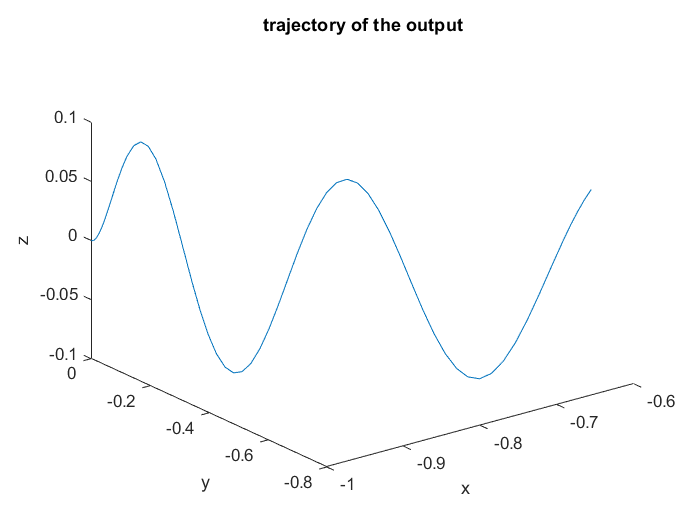

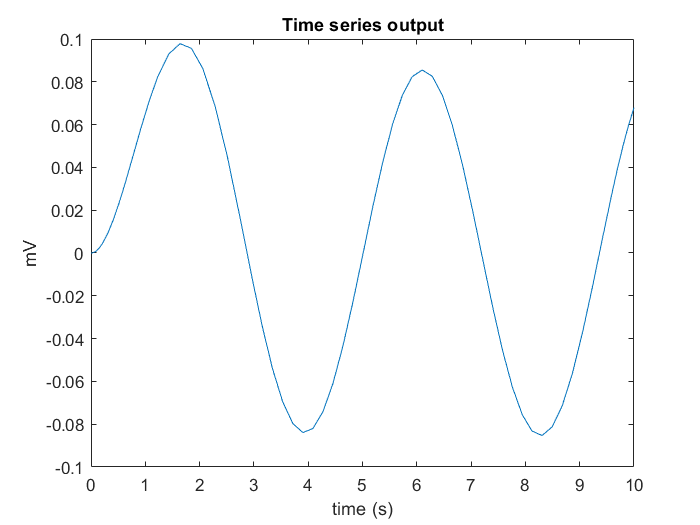

w  = 2*pi/72;
f2 = 0.23;
A  = 0.15;

timelimit = [0 10];
initial_cond = [-1 0 0];

ECG_mod(theta_i,a_i,b_i,w,f2,A,timelimit,initial_cond);

(1 mark)

Complete the function ECG_mod() at the end of this script**. **Write down the ODE following eq (1). You can define auxillary functions ($\alpha, \Delta\theta, z_0$) if you wish, but you can also substitute them directly into dECG.

(4 marks)

### Question 4

Download the measurement.mat file fom Moodle. Manipulate the input parameters of ecg_mod() in such a way, that it achives a normalized cross-correlation (NXC) at least of 0.1. The student with the best solution (highest NXC) will earn an extra 3 marks! 

An example:

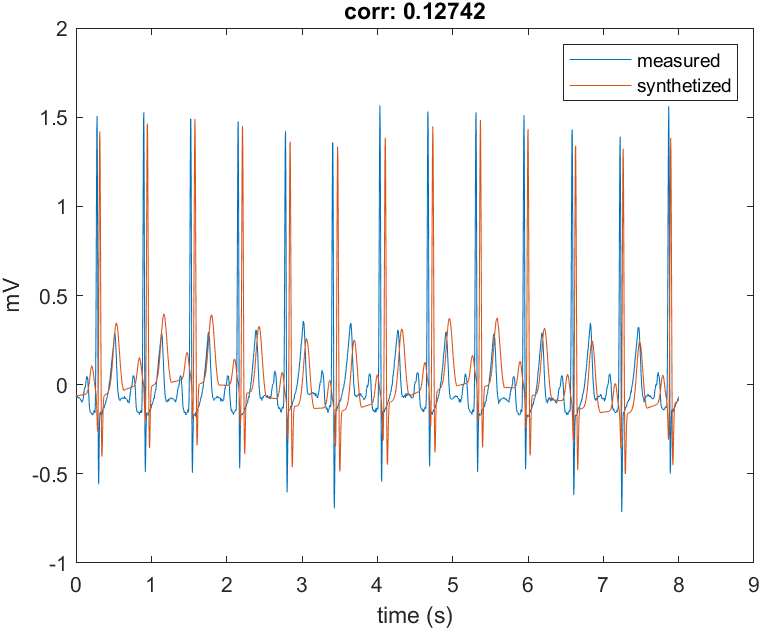

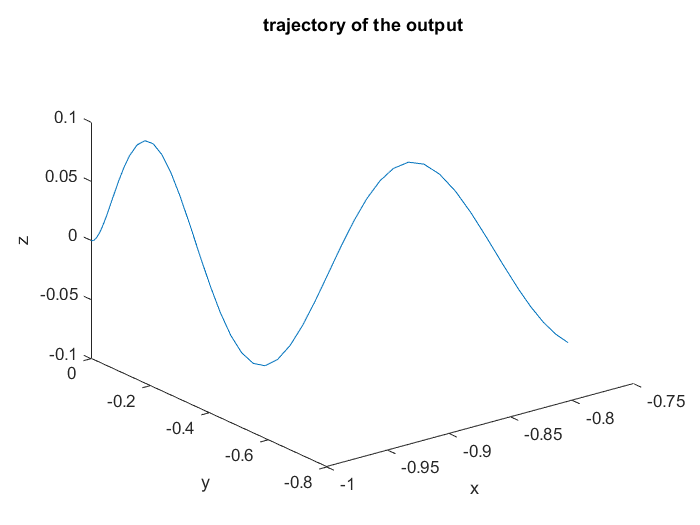

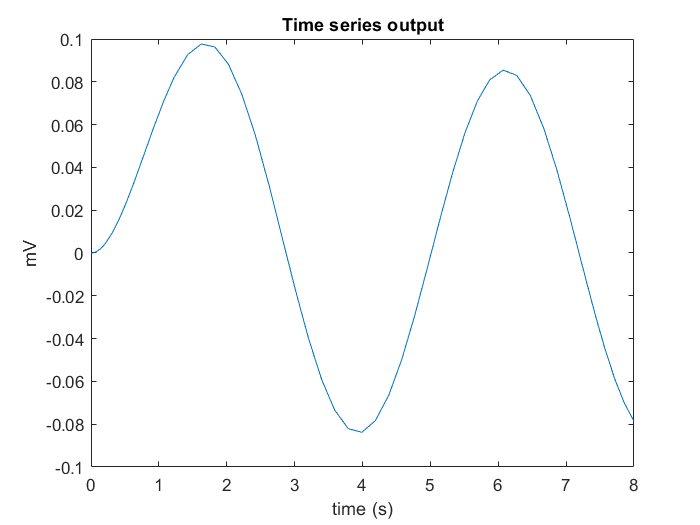

load measurement.mat

figure(10)
clf
plot(t_ecg,ECG)
xlabel('time (s)')
ylabel('mV')


[t,z] = ECG_mod(theta_i,a_i,b_i,w,f2,A,[0 8],initial_cond);



ECG = interp1(t_ecg,ECG,t);
NXC = norm(sum(ECG.*z))/(norm(ECG)*norm(z))

NXC = 0.2933

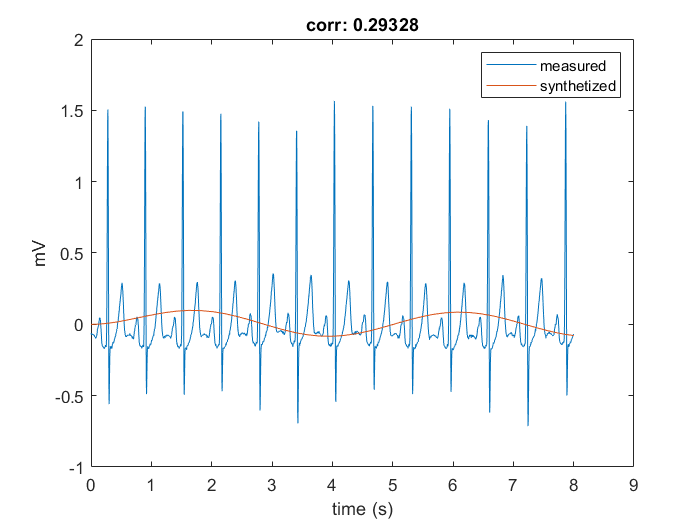



figure(10)
hold on
plot(t,z)
xlabel('time (s)')
ylabel('mV')
legend('measured','synthetized')
title(['corr: ',num2str(NXC)])

(2 marks)

## Functions

function FitzhugNagumo(V0,W0,a,b,I,timelimit)
% differential eq.
FN = @(t, VW) [VW(1)-(VW(1)^3)/3-VW(2)+I;00.8*(VW(1)+a-b*VW(2))];

% solution
[t,VW_sol]=ode45(FN, timelimit, [V0 W0]);

% plotting
subplot(1,2,1)
plot(t,VW_sol(:,1));
xlabel('time (s)')
ylabel('membrane potential (V)');

subplot(1,2,2);
plot(VW_sol(:,1),VW_sol(:,2));
xlabel('potential')
ylabel('recovery');
title('phase plot')

end

function [t,z] =ECG_mod(theta_i,a_i,b_i,w,f2,A,timelimit,initial_cond)
    function d_dt= dECG(t,S,theta_i,a_i,b_i,w,f2,A)
        alpha=1 - sqrt(S(1)^2+S(2)^2);
        theta=atan2(S(2),S(1));
        d_theta = rem(theta-theta_i, 2*pi);
        Z0= A*sin(2*pi*f2*t);
        exp_part= (exp(-(d_theta.^2)./(2*b_i.^2)));
        dx= alpha*S(1)-w*S(2);
        dy= alpha*S(2)+w*S(1);
        dz= -sum(a_i.*d_theta.*exp_part)-(S(3)-Z0);
        d_dt=[dx;dy;dz];
    end

    [t,S_sol] = ode45(@(t,y) dECG(t,y,theta_i,a_i,b_i,w,f2,A),timelimit,initial_cond);

    figure
    plot3(S_sol(:,1),S_sol(:,2),S_sol(:,3))
    xlabel('x')
    ylabel('y')
    zlabel('z')
    title('trajectory of the output')

    figure
    plot(t,S_sol(:,3))
    xlabel('time (s)')
    ylabel('mV')
    title('Time series output')

    z=S_sol(:,3);
end

**Do not forget to generate a pdf report from this file (Save/ Export to PDF). You should upload both the pdf and mlx files to moodle.**